# Práctica 2- Carmen Gallardo y Pablo Mendieta

## Enunciado

Eres el propietario de una de las fábricas de cerveza más grandes de la Comunidad de Madrid que comenzó a operar hace dos años y, en la actualidad, tu marca abastece semanalmente (todas las semanas se produce un envío) a diversos supermercados. Después de estos dos años de trabajo has conseguido recopilar una base de datos en la que cada registro corresponde a los paquetes de cerveza que ha solicitado cada semana uno de los supermercados a los que abasteces (excel adjunto en la práctica). 

Además de la gestión de la demanda, es decir, enviar los paquetes de cerveza que ha solicitado cada uno de los supermercados, cada semana realizas un pedido (que tarda una semana en llegar) de los ingredientes necesarios para fabricar cada uno de los paquetes de cerveza, de forma que si quieres fabricar, por ejemplo 5 paquetes de cerveza, solicitas 5 paquetes de ingredientes (cada paquete de cerveza utiliza un paquete de productos para su fabricación). Puedes suponer que los paquetes de cerveza se fabrican en el mismo instante en que llegan los ingredientes.

Tanto el envío de paquetes de cerveza, como la recepción del pedido de ingredientes de la semana anterior y la realización del nuevo pedido de ingredientes se realizan el mismo día (de forma simultánea). 

Te interesa definir una estrategia para decidir el número de paquetes de ingredientes que has de pedir cada semana con el objetivo de optimizar los beneficios de la fábrica. Para definir dicha estrategia, necesitas probar diferentes métodos y estudiar cuál de ellos proporciona más ganancias. En particular, estás interesado en probar qué ocurre cuando cada semana pides tantos paquetes de ingredientes como paquetes de cerveza fueron demandados por el supermercado del que has recogido los datos en la semana anterior. Estudiarás por tanto un único supermercado, con la idea de aplicar la estrategia que mejor funcione a todos los demás. 

Para poder tomar una decisión, es necesario que observes los resultados de aplicar esta primera estrategia durante al menos un año teniendo en cuenta la siguiente información:

- Cada paquete de cerveza contiene 50 latas. 

- La cantidad que ganas por cada lata de cerveza enviada al supermercado es 2 euros.

- Cada paquete de ingredientes te cuesta 60 euros.

- Cuando no tienes suficientes paquetes de cervezas para entregar al supermercado, entregas tantos paquetes como puedas y, los que no has podido entregar, quedan pendientes de ser entregados en la semana siguiente. 

- Cuando sobran paquetes de cerveza en la fábrica, es decir, cuando has fabricado más paquetes de los que han demandado, estos se quedan en el almacén de la fábrica y pueden ser entregados en semanas posteriores.

- Un año tiene 52 semanas.

- En la primera semana supones que tienes 15 paquetes de cerveza en el almacén de la fábrica contando con los paquetes de ingredientes que has recibido. 

**¿Cuál es la forma que eliges para definir el número de paquetes de cerveza de demanda cada semana? ¿Por qué?**

**¿Consideras que esta primera estrategia es buena? ¿Por qué? Explica todo lo que puedas sobre los resultados que has obtenido de cara a justificar esta decisión.**

**Añade a tus resultados dos gráficos diferentes, uno en el que indiques el número de paquetes de cerveza que hay cada semana en el almacén (puede ser negativo en caso de que debas paquetes de cerveza al supermercado) y otro en el que indiques las ganancias totales cada semana (puede ser negativo en caso de que pierdas dinero). **

**Realiza todo el ejercicio utilizando la semilla rng(42).**

## **Identificación de la distribución de entrada**

clc, clear, clf
rng(42)

datos = xlsread('Pedidos.xlsx');

**Hipótesis sobre la familia de la distribución.**

Calculamos los estadísticos descriptivos de $\textrm{datos}$.

tabla = table(datos)

tabla = 100×1 table
    datos
    _____

      4  
      4  
      6  
      2  
      0  
      0  
      0  
      0  
      0  
      0  
      4  
     10  
      2  
      2  
     20  
     20  


summary(tabla)

Variables:

    datos: 100×1 double

        Values:

            Min           0   
            Median        4   
            Max          60   




desviacion = std(datos)

desviacion = 9.8872

media = mean(datos)

media = 7.8000

asimetria = skewness(datos)

asimetria = 2.5583

Vemos que la media ( 7.80 ) y la mediana ( 4 ) no son similares. Por lo que podría tratarse de una variable asimétrica. Además,  el coeficiente de asimetría ( 2.55) es muy diferente a 0. Por lo que no va a ser simétrica

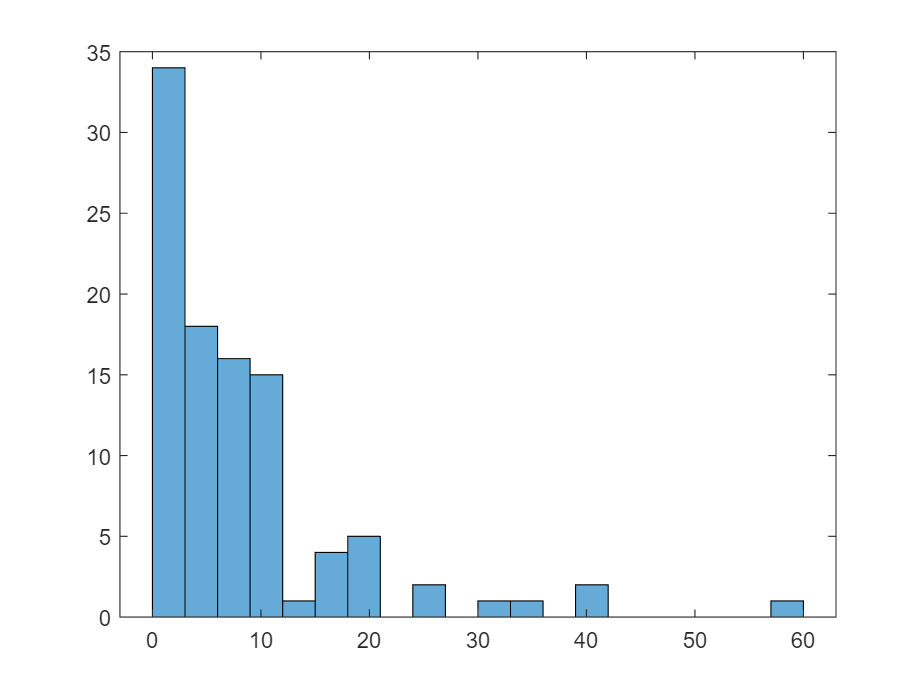

eje = 0:3:max(datos)+1; % Quiero representar intervalos de tamaño 2
histogram(datos,eje)

Vamos a comprobar si la variable $\textrm{datos}$ se distribuye según una $\textrm{Exponencial}$.

Calculamos los estimadores:   

pd = fitdist(datos,'Exponential')

pd =   ExponentialDistribution

  Exponential distribution
    mu = 7.8   [6.47147, 9.58655]


Observamos que el parámetro ajustado para ***mu*** es 7.8. Los  números que aparecen a la derecha de estos valores representan un intervalo de confianza del 95% para las  estimaciones del parámetro.

Primero, representaremos de forma gráfica, sobre el histograma anterior, la distribución teórica de una $\textrm{Exponencial}$ con parámetros igual a los estimados anteriormente.

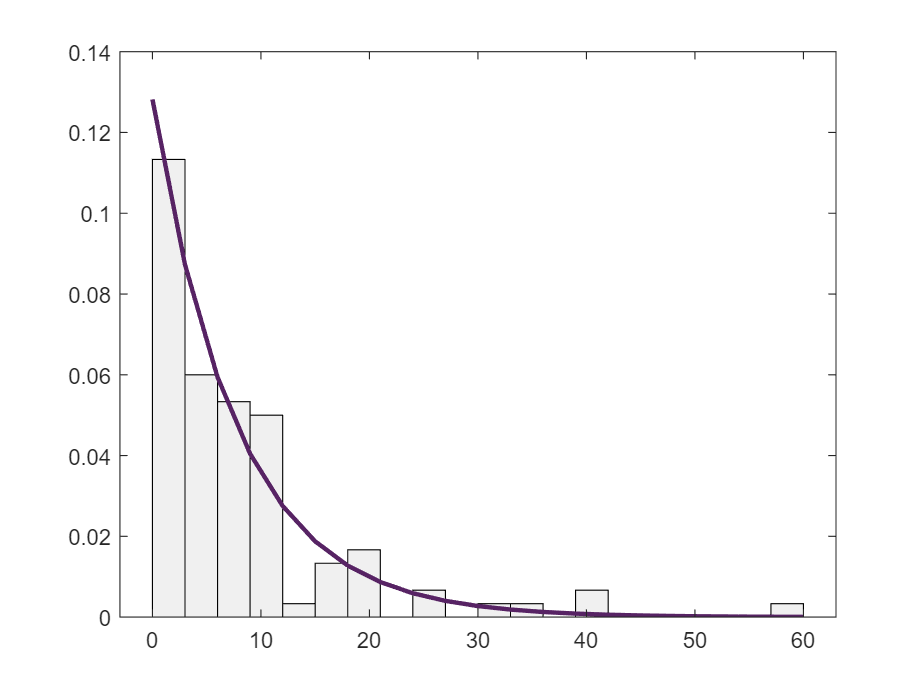

% Histograma de mis datos
h = histogram(datos,eje,'Normalization','pdf','FaceColor',[.9 .9 .9]);
% Densidad teórica
Gamma = pdf(pd,eje); % Función que calcula la densidad con los parámetros datos
line(eje,Gamma,'LineWidth',2,'Color','#572364')
hold off

Observamos que la distribución se aproxima bastante de forma gráfica. En el siguiente paso lo comprobaremos  analíticamente.

Observamos también que la distribución elegida parece ser correcta.  Para probarlo analíticamente tenemos diferentes maneras. En este caso, utilizaremos la prueba de bondad de  ajuste chi-cuadrado.  Definimos como la función de distribución teórica para una **Exponencial** con los parámetros calculados y la  función de distribución particular (empírica) de los datos de entrada respectivamente.  Definimos el siguiente contraste: 


$$\left\lbrace \begin{array}{ll}
H_0 : & F=F_0 \\
H_1 : & F\not= F_1 
\end{array}\right.$$


El resultado h es 1 si RECHAZAMOS la hipótesis nula con un nivel de significación del 5% y 0 en el caso  contrario. En este caso, como queremos que sea cierta, es decir, que ambas funciones de distribución sean 

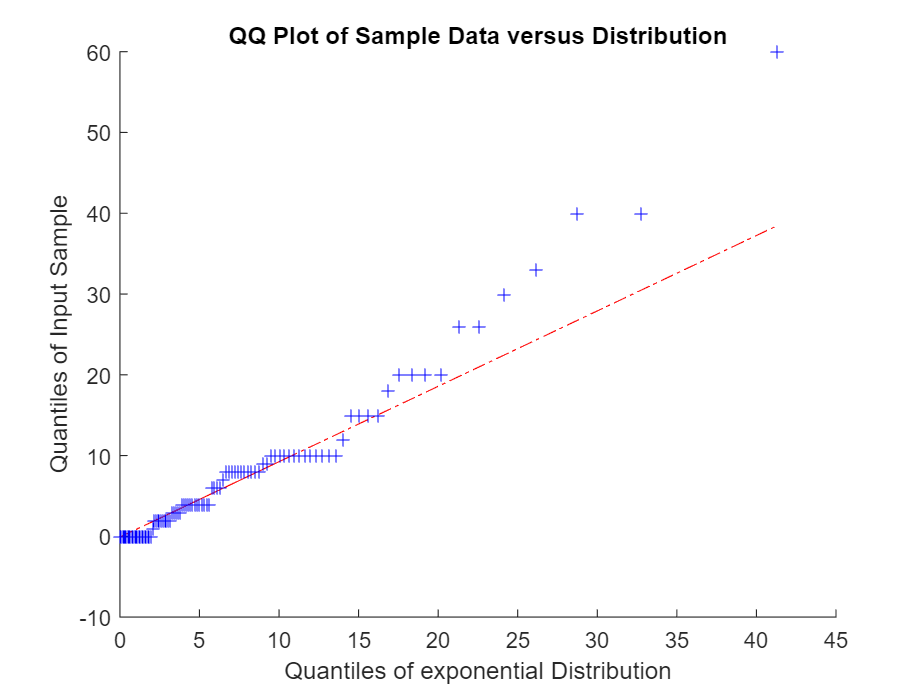

qqplot(datos,pd)

pd 

pd =   ExponentialDistribution

  Exponential distribution
    mu = 7.8   [6.47147, 9.58655]


h = chi2gof(datos,'CDF',pd)

h = 0

Por tanto, tanto analítica como gráficamente hemos visto que los datos de entrada $\textrm{variable}$ , se distribuyen como una $\textrm{Exponecial}\;$de paramétro 7,8 .

Una vez sabemos que distribución que siguen los datos de el problema, pasamos a realizar el modelo:

## Definición de las variables 

Para este problema vamos a tener en cuenta como varaibles de estado el inventario que tengamos y las ganancias por semana. El inventario equivale a el inventario de la semana anterior más los paquetes recibidos de ingredientes menos los paquetes solicitados de cajas.

Como variables auxiliares vamos a utilizar: Un reloj (t), pedidoSolicitado (exponencial con mu=7.8), pedidoIngredientes(pedidoSolicitado de la semana anterior) y paquetesEnviados(Paquetes que se envian cada semana).

## Solución gráfica primer año

tMax = 52; %semanas
t = 1; %inicio
inventario = 15; %inventario inicial
[vectorInventario, vectorGanancias] = fabrica (tMax, t, inventario)

vectorInventario =     15     7    15    13    11     1     1    -7    14    11    12   -15    15    14     3     2     2     6    10     8     5    11     0     5     7     9    13     2    10    11    -9    11     1    -6    15    15    13     6    -3    12     9    -1    10   -11    14     4    12     6    10    10


vectorGanancias =            0         800         320         520         800        1660         920         180       -1140        -800        -740         280       -1520       -1420        -280        -700       -1280       -1860       -1900       -1500       -1120       -1320        -460       -1360       -1460       -1340       -1500        -320        -900        -800          60       -1380        -520       -1260       -2520       -2520       -2320       -1540       -1480       -2560       -2140       -1600       -2560       -1860       -3420       -2380       -2740       -2020       -2060       -1860


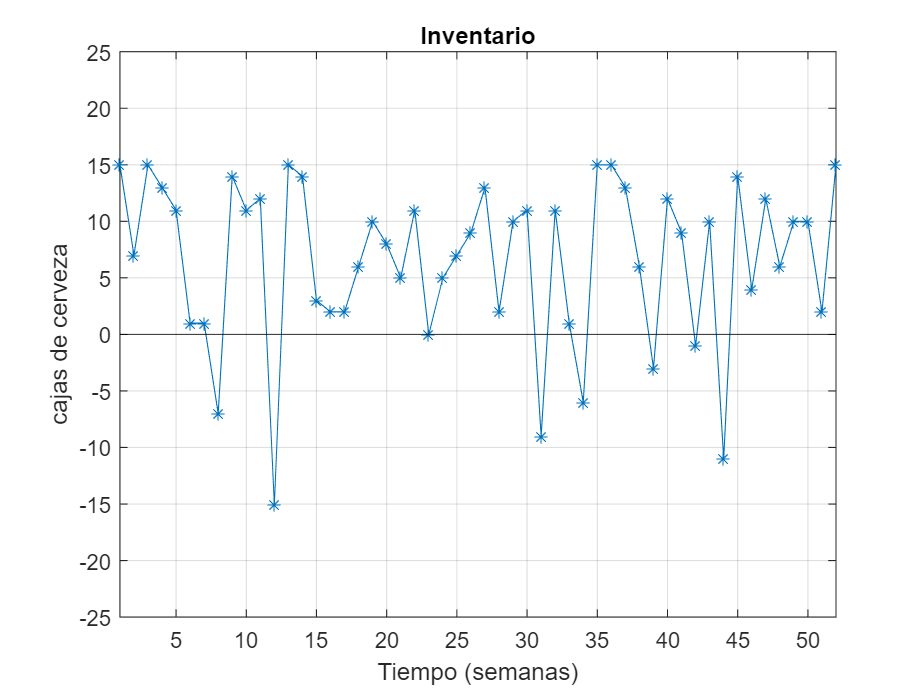


plot(t:tMax,vectorInventario, '-*','Color','#0072BD')
yline(0, 'k')
ylim([-25, 25])
xlim([t,tMax])
xlabel("Tiempo (semanas)")
ylabel("cajas de cerveza")
title("Inventario")
grid on
hold off

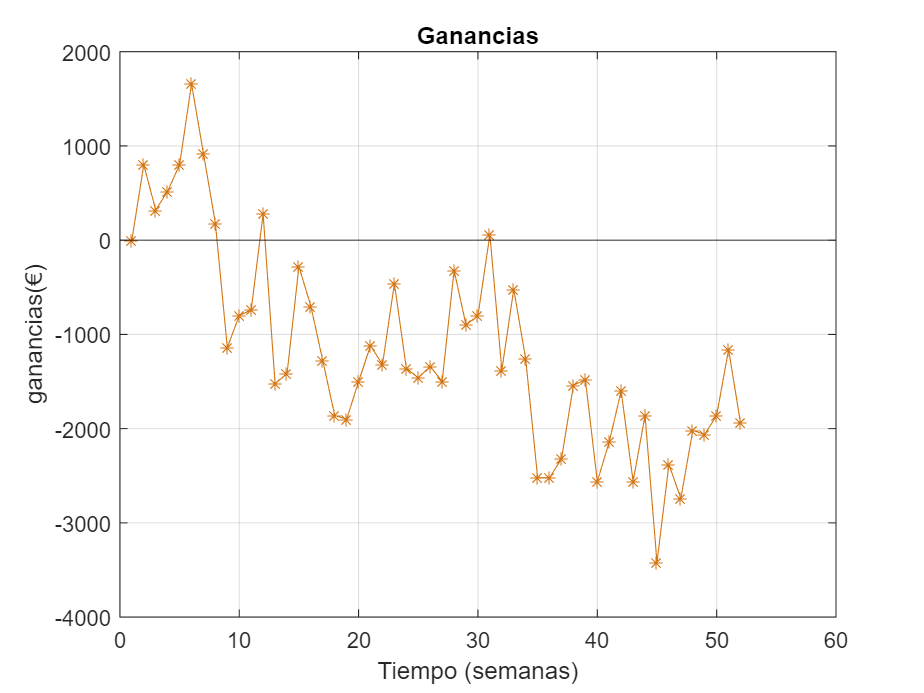


plot(t:tMax,vectorGanancias, '-*','Color','#D37512')
yline(0, 'k')
xlim([0,60])
xlabel("Tiempo (semanas)")
ylabel("ganancias(€)")
title("Ganancias")
grid on
hold off


ultimoValor = vectorGanancias(end);
disp(['El último valor del vector de ganancias es: ', num2str(ultimoValor)]);

El último valor del vector de ganancias es: -1940


disp(['Mayor cantidad a deber: ', num2str(min(vectorGanancias))]);

Mayor cantidad a deber: -3420


## Calculo media anual

Pocedemos a calcular una media anual simulando 500 años. 

n = 500;
vector = [];
media = 0;
for i = 1:n
    [vectorInventario, vectorGanancias] = fabrica (tMax, t, inventario);
    ultimoValor = vectorGanancias(end);
    vector = [vector ultimoValor];
end    
media = sum(vector) / n

media = -335.3600

pd = fitdist(vector','Normal')

pd =   NormalDistribution

  Normal distribution
       mu = -335.36   [-629.611, -41.1087]
    sigma = 3348.89   [3153.39, 3570.42]


ci = paramci(pd,'Alpha',.05)

ci = 	1.0e+03 *

   -0.6296    3.1534
   -0.0411    3.5704


## ¿La estrategía es buena?

Analizando los resultados, observamos que  el intervalo de confianza obtenido para un alpha = 0,05 es [ -629.611, -41.1087 ] , con una media de -335.36. Por otro lado, la desviación típica es de 3348 en un intervalo de [ 3153.39, 3570.42 ]. 

Observando los datos en las gráficas y estos últimos donde analizamos la media para 500 años, se concluye que la estrategia de pedir cada semana tantos paquetes de ingredientes como paquetes de cerveza fueron demandados por el supermercado del que has recogido los datos en la semana anterior,** no ha dado los resultados esperados**.  Como podemos observar en la gráfica de las ganancias a partir de la semana 7 (aproximadamente) empieza a perder dinero. Al rededor de la semana 44 llega a deber 3420 € y acaban el año con unas pérdidas de 1940 €. Por otro lado, como la media para los 500 años es negativa, podemos afirmar que las ganacias van a ser, en media, negativas. 

    A favor de esta estrategia podemos observar que el inventario nunca supera las 15 unidades, por lo que minimiza muy bien la cantidad de inventario, objetivo que se busca para minimizar las pérdidas ( muchas unidades sin vender = pérdida de dinero ). Si estuvieramos teniendo en cuenta el dinero que nos cuesta mantener dentro del almacen las cajas, a lo mejor podríamos ahorrar algo con esta estrategia. 

function [vectorInventario, vectorGanancias] = fabrica (tMax, t, inventario)
    %definicion de variables iniciales
    pedidoSolicitado = max(0, round(exprnd(7.8)));
    pedidoIngredientes = 0;
    ganancias = 0;
    vectorInventario = inventario;
    vectorGanancias = ganancias;
    while t< tMax

        % calculamos los paquetes que vamos a enviar enviados
        paquetesEnviados = max(0,min(inventario, pedidoSolicitado));

        %calculamos las ganancias semanales
        gastos = 60 * pedidoIngredientes;
        ganancias = ganancias + paquetesEnviados * 100 - gastos;

        % añadimos el pedido de ingrendientes
        inventario = inventario + pedidoIngredientes;

        % restamos el pedido solicitado
        inventario = inventario - pedidoSolicitado;

        % pedimos para la semana i+1 los pedidos solicitado en la semana i.
        pedidoIngredientes = pedidoSolicitado;
        
        % el pedido solicitado de la semana i + 1
        pedidoSolicitado = max(0, round(exprnd(7.8)));
        
        vectorInventario = [vectorInventario, inventario];
        vectorGanancias = [vectorGanancias, ganancias];
        t = t+1;
    end    

end
